clear; close all; clc

## Experiment 1 - Bepaling l

syms g l theta(t) omega(t)

eqs = [diff(theta,t) == omega;
       diff(omega,t) == (3/4)*(g/l)*theta];

sol = dsolve(eqs,[theta(0)==0.01, omega(0)==0]);
theta = simplify(sol.theta)

$$theta = \frac{\cosh\left(\frac{\sqrt{3}\,\sqrt{g}\,t}{2\,\sqrt{l}}\right)}{100}$$

g_n = 9.81;
t = 0:0.05:(400-1)*0.05;
phi_max = pi/2.1;

data = readmatrix('pendulum_states_exp1bisbisbis.csv');    theta_sim = data(:,3);
% data = readmatrix('pendulum_measurements_exp1.csv');    theta_sim = data(:,2);
l_opt = fminsearch(@(l) theta_mse(l,t,matlabFunction(theta),theta_sim, g_n, phi_max), 0.10);
disp("Optimale lengte l = " + l_opt)

Optimale lengte l = 0.13547


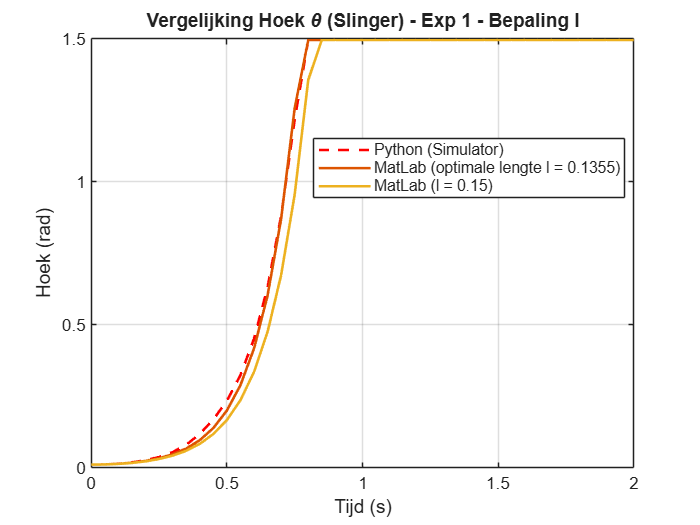

theta_fun_opt = matlabFunction(subs(theta,[g,l],[g_n,l_opt]));
theta_model_opt = theta_fun_opt(t);

theta_fun_015 = matlabFunction(subs(theta,[g,l],[g_n,0.15]));
theta_model_015 = theta_fun_015(t);

theta_model_opt = min(theta_model_opt,phi_max);
theta_model_015 = min(theta_model_015,phi_max);

figure
plot(t,theta_sim,'r--','LineWidth',1.5); hold on
plot(t,theta_model_opt,'LineWidth',1.5)
plot(t,theta_model_015,'LineWidth',1.5)
xlabel('Tijd (s)')
xlim([0,2]);
ylabel('Hoek (rad)')
title('Vergelijking Hoek \theta (Slinger) - Exp 1 - Bepaling l')
legend('Python (Simulator)',sprintf('MatLab (optimale lengte l = %0.4f)',l_opt), 'MatLab (l = 0.15)','Location','best')
grid on

## Experiment 1bis - Bepaling l

% data = readmatrix('pendulum_measurements_exp1bis.csv');
% theta_sim = data(:,2);
% theta_sim(theta_sim < 0) = theta_sim(theta_sim < 0) + 2*pi;
% 
% [pks, locs] = findpeaks(theta_sim, t)
% periods = diff(locs)
% T = mean(periods)
% l = (T/(pi))^2*3*g_n/16
% figure
% plot(t,theta_sim,'r--','LineWidth',1.5); hold on
% xlabel('Tijd (s)')
% xlim([0,10]);
% ylabel('Hoek (rad)')
% title('Vergelijking Hoek \theta (Slinger) - Exp 1bis - Bepaling l')
% legend('Python (Simulator)')%,'MatLab (optimale lengte l = 0.12152)', 'MatLab (l = 0.15)','Location','best')
% grid on

## Experiment 2 - Bepaling b en M+m

syms Mplusm b F v(t) x(t) t

eqn = [diff(x) == v,(Mplusm)*diff(v) + b*v == F]

$$eqn(t) = \left(\begin{array}{cc} \frac{\partial }{\partial t}x\left(t\right)=v\left(t\right) & \mathrm{Mplusm}\,\frac{\partial }{\partial t}v\left(t\right)+b\,v\left(t\right)=F \end{array}\right)$$

sol = dsolve(eqn,[x(0)==0, v(0)==0]);
x = simplify(sym(sol.x))

$$x = \frac{F\,\mathrm{Mplusm}\,{\mathrm{e}}^{-\frac{b\,t}{\mathrm{Mplusm}}}-F\,\mathrm{Mplusm}+F\,b\,t}{b^{2}}$$

x_fun = matlabFunction(sol.x, 'Vars', {t, Mplusm, b, F})

x_fun = function_handle with value:
    @(t,Mplusm,b,F)(F.*t)./b+(Mplusm.*exp(-(b.*t)./Mplusm).*(F./b-(F.*exp((b.*t)./Mplusm))./b))./b


t = 0:0.05:(400-1)*0.05;
x_max = 0.9;
F = 0.01;

data = readmatrix('pendulum_states_exp2bisbis.csv');
% data = readmatrix('pendulum_measurements_exp2bisbis.csv');

x_sim = data(:,1);
x_sim = min(x_sim,x_max);

params0 = [1.78, 0.178];  % startwaarden
params_opt = fminsearch(@(p) x_mse(p, t, x_fun, x_sim, x_max, F), params0);

M_plus_m_opt = params_opt(1);
b_opt = params_opt(2);

disp(['Optimale M+m = ', num2str(M_plus_m_opt), ', b = ', num2str(b_opt)])

Optimale M+m = 0.69997, b = 0.10001


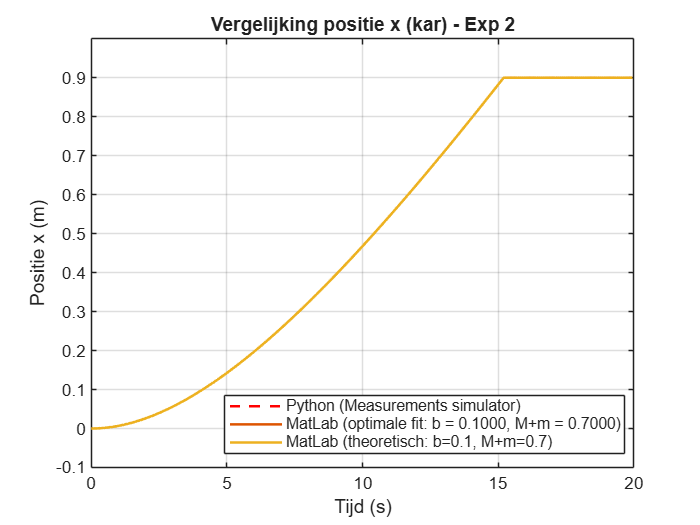

x_model_opt = x_fun(t,M_plus_m_opt,b_opt,F);
x_model_theory = x_fun(t,0.7,0.1,F);  % puur theoretisch

x_model_opt = min(x_model_opt,x_max);
x_model_theory = min(x_model_theory,x_max);

figure
plot(t,x_sim,'r--','LineWidth',1.5); hold on
plot(t,x_model_opt,'LineWidth',1.5)
plot(t,x_model_theory,'LineWidth',1.5)
xlabel('Tijd (s)')
ylabel('Positie x (m)')
xlim([0,20]); ylim([-0.1 1]);
title('Vergelijking positie x (kar) - Exp 2')
legend(sprintf('Python (Measurements simulator)'),sprintf('MatLab (optimale fit: b = %0.4f, M+m = %0.4f)',b_opt, M_plus_m_opt),sprintf('MatLab (theoretisch: b=0.1, M+m=0.7)'),'Location','best')
grid on

## Experiment 3 - Bepaling m en M

% m = 0.2, M = 0.5
syms m M
% l_opt = 0.15

data = readmatrix('pendulum_states_exp1.csv');    
x_sim = data(:,1);
theta_sim = data(:,3);

#### Puur massacentrum begintoestand = eindtoestand

x_kar_0 = x_sim(1);
[x_kar_1, idx] = max(x_sim)

x_kar_1 = 0.0413

idx = 16

t(idx)

ans = 0.7500

theta_0_pend = theta_sim(1);
theta_1_pend = theta_sim(idx);
x_pend_0 = x_kar_0 - l_opt*sin(theta_0_pend);
x_pend_1 = x_kar_1 - l_opt*sin(theta_1_pend);
x_center_mass_0 = (m*x_pend_0 + M*x_kar_0)/(m+M);
x_center_mass_1 = (m*x_pend_1 + M*x_kar_1)/(m+M);
eqns = [x_center_mass_0 == x_center_mass_1, M+m == M_plus_m_opt];
[M m] = solve(eqns, [M m]);
disp(vpa(M,4))

$$0.4836$$

disp(vpa(m,4))

$$0.2163$$

#### Least mean square error op de volledige dataset -> beter

% l_opt = 0.15
x_sim = x_sim(1:16);      % Positie kar
theta_sim = theta_sim(1:16); % Hoek pendulum (rad)

% 2. Optimizatie: Zoek de 'm' die het zwaartepunt het meest constant houdt
% We weten dat M + m = M_plus_m_opt (uit vorig experiment)
m_start = 0.3; 
m_opt = fminsearch(@(m) massacentrum_mse(m, x_sim, theta_sim, l_opt, M_plus_m_opt), m_start);
M_opt = M_plus_m_opt - m_opt;

fprintf('Optimale resultaten Exp 3:\n');

Optimale resultaten Exp 3:


fprintf('Massa Pendulum (m): %.4f kg\n', m_opt);

Massa Pendulum (m): 0.2167 kg


fprintf('Massa Kar (M): %.4f kg\n', M_opt);

Massa Kar (M): 0.4833 kg


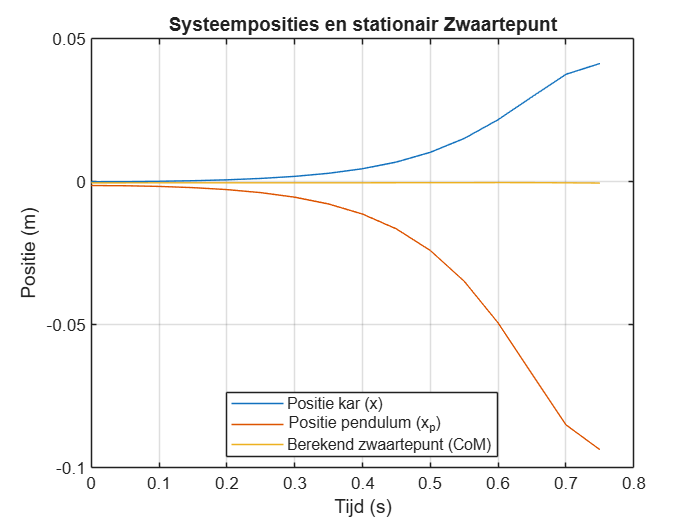

x_pend_sim = x_sim - l_opt * sin(theta_sim);
x_com_opt = (m_opt * x_pend_sim + M_opt * x_sim) / M_plus_m_opt;

figure;
plot(t(1:16), x_sim, 'DisplayName', 'Positie kar (x)'); hold on;
plot(t(1:16), x_pend_sim, 'DisplayName', 'Positie pendulum (x_p)');
plot(t(1:16), x_com_opt, 'DisplayName', 'Berekend zwaartepunt (CoM)');
title('Systeemposities en stationair zwaartepunt');
xlabel('Tijd (s)'); ylabel('Positie (m)');
legend('show','Location','best'); grid on;

## Conclusie

fprintf('Optimale resultaten:\n'); fprintf('Massa Pendulum (m): %.4f kg\n', m_opt); fprintf('Massa Kar (M): %.4f kg\n', M_opt); fprintf('Halflengte pendulum (l): %.4f m\n', l_opt'); fprintf('Wrijvingscoëfficïent (b): %.4f Ns/m\n', b_opt')

Optimale resultaten:
Massa Pendulum (m): 0.2167 kg
Massa Kar (M): 0.4833 kg
Halflengte pendulum (l): 0.1355 m
Wrijvingscoëfficïent (b): 0.1000 Ns/m


function mse = theta_mse(l,t,theta_fun,theta_sim,g, phi_max)
    theta_model = theta_fun(g,l,t);
    theta_model = min(theta_model,phi_max);
    mse = mean((theta_sim - theta_model').^2);
end

function mse = x_mse(p, t, x_fun, x_sim, x_max, F)
    Mplusm = p(1);b = p(2);
    x_model = x_fun(t, Mplusm, b, F);
    x_model = min(x_model,x_max);
    mse = mean((x_sim - x_model').^2);
end

function var_error = massacentrum_mse(m, x_kar, theta, l, M_total)
    M = M_total - m;
    if m < 0 || M < 0
        var_error = 1e10;
        return;
    end
    x_pend = x_kar - l * sin(theta);
    x_com = (m * x_pend + M * x_kar) / M_total;
    var_error = mean((x_com - mean(x_com)).^2);
end